# Newton's Method

## Introduction

Recall that $x=a$ is a root (or a zero) of a function $f\left(x\right)$, if $f\left(a\right)=0$. Newton's method (or the Newton–Raphson Method) is used to find an approximate root of a function $f\left(x\right)$ by computing successive approximations using the formula

$x_n =x_{n-1} -\frac{f\left(x_{n-1} \right)}{f^{\prime } \left(x_{n-1} \right)}$ for $n=2,3,4,\dots$

for some initial approximation $x_1$ to a root of $f\left(x\right)$. 

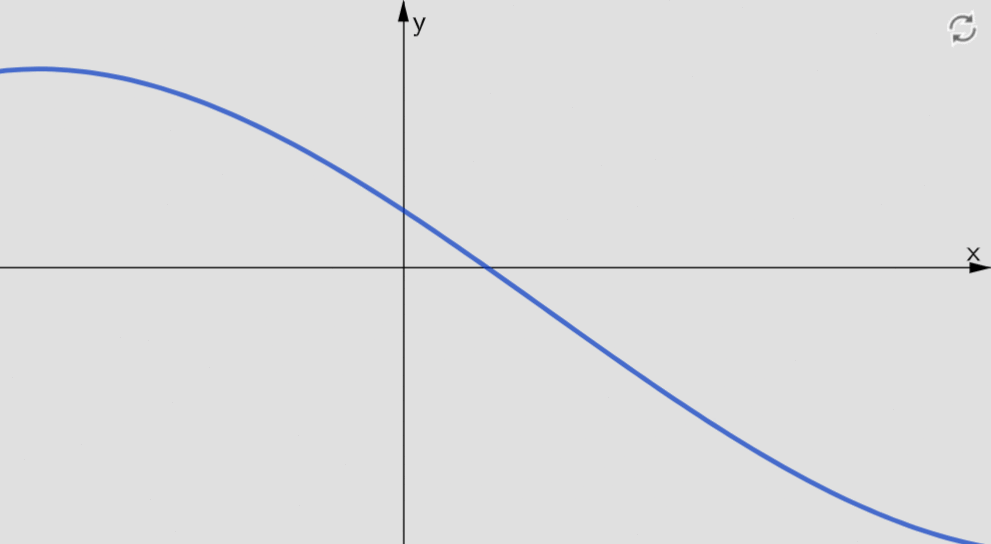

The method is useful when the root of $f\left(x\right)$ cannot be obtained analytically and is often used an alternative to the [Bisection method](https://mathworld.wolfram.com/Bisection.html). However, Newton's method requires that the function $f\left(x\right)$, and the initial guess $x_1$, satisfy the following conditions:

- the derivative of $f\left(x\right)$ can be calculated;

- the derivative is continuous around the root;

- the initial approximation $x_1$ is sufficiently close to a root of $f\left(x\right)$; and

- the derivative at $x_1$ is nonzero.

In this activity, we will learn how to implement Newton's method in MATLAB.

## **Before starting**

Use the **MATLAB** **Live Editor** to **edit** and **run** this **Live Script** in your browser or your desktop.

- Read each section carefully. 

- Run the code within a section before starting to read the next. 

- To run the code from each section, position the *cursor* on the code with the mouse and then click on the **Run Section** button (from the toolstrip) or click on the blue stripe on left side of that section as shown below:

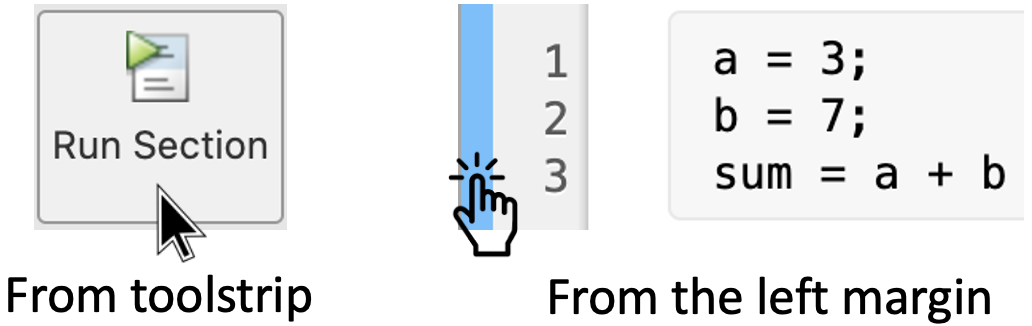

**Remark:** Run the code of each section from top to bottom, otherwise you may get an error.

- *The end of a section is indicated with a thin line, like the next one* -

## 1. Worked example

Suppose we want to find the root of the function

$f\left(x\right)=x^3 -5$.

To check out in which range the root is, we first plot $f\left(x\right)$ in the range $-3\le x\le 3$ as follows:

clear
syms x
fplot(x^3-5,[-3 3])
grid on, xlabel('x'), ylabel('f(x)')
title('Plot of f(x) = x^3-5')

The graph indicates that $f\left(x\right)$ intersects the $x$-axis in the range $1\le x\le 2$. This means that the root we are looking for is within this interval. So, we can choose $x_1 =1$ as our initial approximation. However, we can choose any other value as long as it is sufficiently close to the root of $f\left(x\right)$.

### 1.1 Naive implementation

Since $f\left(x\right)=x^3 -5$, we have that $f^{\prime } \left(x\right)=3x^2$. Newton's iteration scheme takes the form

$x_n =x_{n-1} -\frac{x_{n-1}^3 -5}{{3x}_{n-1}^2 }$ for $n=2,3,4,\dots$

To perform all the calculations, we need to define our own **function** for $f\left(x\right)=x^3 -5$ named `fun`:

and its **derivative **$f^{\prime } \left(x\right)=3x^2$ named `funp`:

These user-defined functions are allocated at the end of this document, see Appendix.

Now, we set as our initial approximation:

x1 = 1

Then the first 5 iterations are:

format long
x2 = x1 - fun(x1)/funp(x1)
x3 = x2 - fun(x2)/funp(x2)
x4 = x3 - fun(x3)/funp(x3)
x5 = x4 - fun(x4)/funp(x4)
x6 = x5 - fun(x5)/funp(x5)

**Remark:** By default, MATLAB shows the output with only 4 decimal places. In this context it is better to see the output with more decimals using the command [`format`](https://au.mathworks.com/help/matlab/ref/format.html).

We can take the value of `x6` as a good approximation of the root of $f\left(x\right)=x^3 -5$. Run this section to see the value of $f\left(x_6 \right)$:

fun(x6)

Notice that the output is very small, almost zero. Here MATLAB uses the scientific notation `3.6e-08`. It means $3\ldotp 6\times {10}^{-8}$. If we want more precision, we need to calculate more iterations. However, the previous method is not very efficient, since we will need to rewrite line by line over and over again. This problem can be solved using a `for` or `while` loop.

### 1.2 Implementation using a `for` loop

With a for loop we can control the number of iterations we want to calculate. First, we must set our initial value:

x = 1

And now we just need to write the `for` loop:

for n = 1:5                  % For every value of n from 1 to 5
    x = x - fun(x)/funp(x)   % Perform this calculation
end                          % Exit "for" loop
fun(x)                       % Calculate f(x) which is approx 0

That's it! Run this section and compare with the previous outputs.

Now modiy the code. Change the number of iterations to 10, 20 or 50 and then re-run this section. What do you notice? What do you wonder?

### 1.3 Implementation using `while` loop

We could easily adapt the `for` loop as a `while` loop to obtain the same result:

However, we would like to add extra conditions to calculate a better approximation of the root. Here is where the while loop turns out to be a very useful tool.

For example, we are happy if the difference between successive iterates is smaller than ${10}^{-5}$, that is$|x_{n+1} -x_n |\le {10}^{-5}$. We also do not want that the number of iterations gets too large, so we restrict $n$ to $n\le 25$. Thus, we write:

x=1;                             % Set starting value
nmax=25;                         % Set max number of iterations
eps=1;                           % Initialise error bound "eps"
n=0;                             % Initialise "n" (counts iterations)

while eps >= 1e-5 && n <= nmax   % Set while-conditions
    y = x - fun(x)/funp(x);      % Compute next iterate using a different 
                                 % variable to calculate the error
    eps = abs(y-x);              % Compute error
    x = y;                       % Update "x"
    n = n + 1;                   % Update "n" by 1
end                              % Exit the while loop
n                                % Display the number of iterations
x                                % Display the last value of "x"
fun(x)                           % Calculate f(x) which is approx 0

**Remark:** Notice we use the scientific notation `1e-5`. It means $1\times {10}^{-5}$. In other words, 0.00001.

Run this section and compare the results with those obtained with the `for` loop. Is this a better approximation?

## 2. Hands on practice!

Let's practice what we just learned.

### Activity:

Use Newton's method to approximate the root of the function


$$f(x)=3x^4-8x^3+2$$


in the interval $2\leq x\leq3$. (Also make sure that $f$ actually has a root in that interval). Define this function and its derivative in the appendix with an appropriate name, similarly to those in section 1.1. Use a `for` loop and then a `while` loop to compare the results. Which method is more accurate?

Write your code with a `for` loop here:

Write your code with a `while` loop here:

## Appendix: User-defined functions

function y = fun(x)
    y = x^3-5;
end


function yprime = funp(x)
    yprime = 3*x^2;
end

% Write your functions after this comment %



% Write your functions before this comment %
